% rgb
map=([1 1 0; 1 0 0; 0 1 1; 0.2 0.2 0.2; 1 0 1; 0.8 0.8 0.8])

map =     1.0000    1.0000         0
    1.0000         0         0
         0    1.0000    1.0000
    0.2000    0.2000    0.2000
    1.0000         0    1.0000
    0.8000    0.8000    0.8000


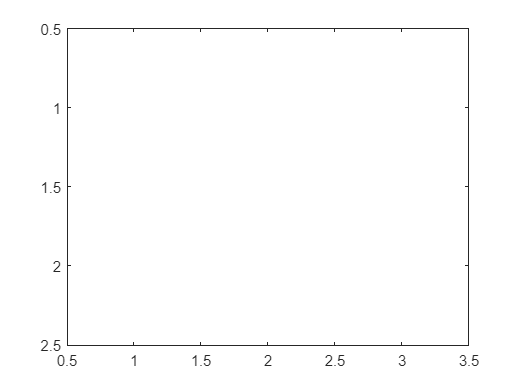

image([1 , 2 , 3; 4, 5, 6])
colormap(map)

N=[1 2 3; 4 5 6; 7 8 9; 10 11 12; 13 14 15]

N =      1     2     3
     4     5     6
     7     8     9
    10    11    12
    13    14    15


N(1:3:end, 1)

ans =      1
    10


N(1:3:end, :)

ans =      1     2     3
    10    11    12


v1=[1, 1, 1, 1]

v1 =      1     1     1     1


v2=[0.5, 0.25, 0, 0.25];
v3=[0.25, 0.5, 0, 0.5, 1]

v3 =     0.2500    0.5000         0    0.5000    1.0000


v1 .* v2

ans =     0.5000    0.2500         0    0.2500


s1=sum(v1 .* v2)

s1 = 1

%v1 .* v3
%s2=sum(v1 .* v3);

m6=[1 2 3; 4 5 6; 7 8 9];
m7=[-2 3 1; 0 2 -7; 1 3 6];

u1= m6>3

u1 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u2= (m6 > 3 & m7==-7)

u2 = 3×3 logical array
   0   0   0
   0   0   1
   0   0   0


u3= (m6 > 3 | m7==-7)

u3 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u4= ( (m6+m7) >= 4 & m6>5)

u4 = 3×3 logical array
   0   0   0
   0   0   0
   1   1   1


bild = imread('Butterfly.tif');
fargbild = double(bild) / 255;
mygray = (fargbild(:,:,1) + fargbild(:,:,2) + fargbild(:,:,3))/3;
imwrite(mygray, 'mygray.png');

mygrey = imread('mygray.png');
b61 = mygrey(1:2:end, 1:2:end);
imwrite(b61, 'b61.png');

b63_nearest = imresize(b61, 2, 'nearest');
b63_linear = imresize(b61, 2,'bilinear');
b63_cubic = imresize(b61, 2,'bicubic');

imwrite(b63_nearest, 'b63_nearest.png');
imwrite(b63_linear, 'b63_linear.png');
imwrite(b63_cubic, 'b63_cubic.png');

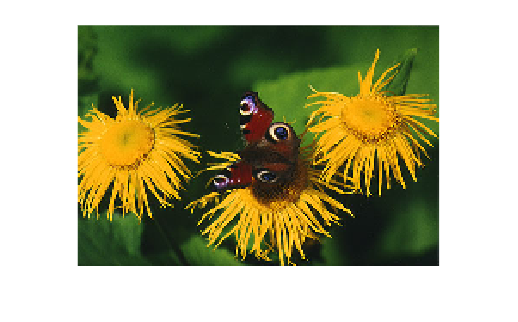

mycolorimage = imread('Butterfly.tif');
mycolorimage = double(mycolorimage)/255;
b64 = imresize(mycolorimage, 0.5, 'nearest');
b64 = imresize(b64, 2, 'nearest');
imshow(b64)

imwrite(b64, 'b64.png');

%6.5
mycolorR = mycolorimage(:, :, 1);
mycolorG = mycolorimage(:, :, 2);
mycolorB = mycolorimage(:, :, 3);

R2 = imresize(mycolorR, 0.5, 'nearest');
R2 = imresize(R2, 2, 'nearest');

B2 = imresize(mycolorB, 0.5, 'nearest');
B2 = imresize(B2, 2, 'nearest');

b65(:,:,1) = R2

b65 = 280×420 uint8 matrix
   53   53   48   48   49   49   48   48   45   45   46   46   40   40   43   43   49   49   53   53   56   56   53   53   54   54   53   53   53   53   49   49   56   56   51   51   49   49   44   44   50   50   47   47   42   42   41   41   41   41
   53   53   48   48   49   49   48   48   45   45   46   46   40   40   43   43   49   49   53   53   56   56   53   53   54   54   53   53   53   53   49   49   56   56   51   51   49   49   44   44   50   50   47   47   42   42   41   41   41   41
   50   50   49   49   47   47   52   52   52   52   48   48   42   42   43   43   50   50   53   53   52   52   54   54   52   52   54   54   54   54   50   50   46   46   49   49   51   51   54   54   50   50   45   45   47   47   44   44   43   43
   50   50   49   49   47   47   52   52   52   52   48   48   42   42   43   43   50   50   53   53   52   52   54   54   52   52   54   54   54   54   50   50   46   46   49   49   51   51   54   54   50   50   45   45

b65(:,:,2) = mycolorG

b65 = 280×420×2 uint8 array
b65(:,:,1) =

    53    53    48    48    49    49    48    48    45    45    46    46    40    40    43    43    49    49    53    53    56    56    53    53    54    54    53    53    53    53    49    49    56    56    51    51    49    49    44    44    50    50    47    47    42    42    41    41    41    41    40    40    39    39    39    39    36    36    40    40    37    37    31    31    36    36    36    36    37    37    37    37    34    34    32    32    33    33    34    34    32    32    32    32    35    35    33    33    32    32    34    34    34    34    32    32    34    34    35    35    33    33    34    34    33    33    32    32    30    30    30    30    29    29    29    29    27    27    27    27    27    27    30    30    31    31    32    32    32    32    31    31    30    30    34    34    28    28    31    31    28    28    34    34    33    33    34    34    31    31    35    35    33    33    37    37    34    34    31    

b65(:,:,3) = B2

b65 = 280×420×3 uint8 array
b65(:,:,1) =

    53    53    48    48    49    49    48    48    45    45    46    46    40    40    43    43    49    49    53    53    56    56    53    53    54    54    53    53    53    53    49    49    56    56    51    51    49    49    44    44    50    50    47    47    42    42    41    41    41    41    40    40    39    39    39    39    36    36    40    40    37    37    31    31    36    36    36    36    37    37    37    37    34    34    32    32    33    33    34    34    32    32    32    32    35    35    33    33    32    32    34    34    34    34    32    32    34    34    35    35    33    33    34    34    33    33    32    32    30    30    30    30    29    29    29    29    27    27    27    27    27    27    30    30    31    31    32    32    32    32    31    31    30    30    34    34    28    28    31    31    28    28    34    34    33    33    34    34    31    31    35    35    33    33    37    37    34    34    31    


imwrite(b65, 'b65.png');

%6.7
R = mycolorimage(:, :, 1)

R =     0.1490    0.1725    0.1490    0.1765    0.2078    0.1961    0.1961    0.1765    0.1804    0.1647    0.1647    0.1725    0.1647    0.1529    0.1569    0.1765    0.1647    0.1843    0.1961    0.2000    0.2078    0.2275    0.2314    0.2157    0.2235    0.2157    0.2078    0.2078    0.2078    0.2078    0.2000    0.1961    0.1765    0.2039    0.2157    0.2039    0.1961    0.2039    0.2039    0.2000    0.1725    0.1725    0.1804    0.1804    0.1725    0.1725    0.1804    0.1843    0.1686    0.1647
    0.1882    0.2078    0.1804    0.1882    0.2078    0.1922    0.1961    0.1882    0.1765    0.1765    0.1804    0.1804    0.1686    0.1569    0.1608    0.1686    0.1686    0.1922    0.2039    0.2078    0.2078    0.2196    0.2196    0.2078    0.2118    0.2118    0.2078    0.2078    0.2118    0.2078    0.2000    0.1922    0.2196    0.2196    0.2118    0.2000    0.1922    0.1922    0.1843    0.1725    0.1961    0.1961    0.1922    0.1843    0.1725    0.1647    0.1647    0.1608    0.1608    0

G = mycolorimage(:, :, 2);
B = mycolorimage(:, :, 3);

R3 = imresize(R, 0.5, 'nearest');
R3 = imresize(R3, 2, 'nearest');

G3 = imresize(G, 0.5, 'nearest');
G3 = imresize(G3, 2, 'nearest');

b67(:,:,1) = R3

b67 = 280×420×3 uint8 array
b67(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

b67(:,:,2) = G3

b67 = 280×420×3 uint8 array
b67(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

b67(:,:,3) = B

b67 = 280×420×3 uint8 array
b67(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  


imwrite(b67, 'b67.png');

%6.8
clear b68
bild1 = R + G + B

bild1 =     0.5451    0.6157    0.5451    0.6275    0.7216    0.6863    0.6863    0.6275    0.6314    0.5843    0.5922    0.6157    0.6000    0.5725    0.5843    0.6471    0.5922    0.6510    0.6980    0.7059    0.7490    0.8039    0.8157    0.7765    0.7961    0.7725    0.7490    0.7490    0.7490    0.7490    0.7255    0.7137    0.6471    0.7294    0.7647    0.7294    0.7059    0.7294    0.7294    0.7176    0.6275    0.6275    0.6510    0.6588    0.6353    0.6392    0.6627    0.6745    0.6314    0.6235
    0.6627    0.7216    0.6392    0.6627    0.7216    0.6745    0.6863    0.6627    0.6196    0.6196    0.6392    0.6392    0.6118    0.5843    0.5961    0.6235    0.6118    0.6745    0.7216    0.7333    0.7490    0.7843    0.7804    0.7529    0.7608    0.7608    0.7490    0.7490    0.7608    0.7490    0.7255    0.7020    0.7765    0.7765    0.7529    0.7176    0.6941    0.6941    0.6706    0.6353    0.6980    0.6980    0.6863    0.6706    0.6353    0.6157    0.6157    0.6039    0.6078 

bild2 = R - G;
bild3 = R + G - 2*B;
bild2 = imresize(bild2, 0.5, 'nearest');
bild2 = imresize(bild2, 2, 'nearest');
bild3 = imresize(bild3, 0.5, 'nearest');
bild3 = imresize(bild3, 2, 'nearest');
b68(:,:,1) = bild1/3+bild2/2+bild3/6;
b68(:,:,2) = bild1/3-bild2/2+bild3/6;
b68(:,:,3) = bild1/3-bild3/3

b68 = b68(:,:,1) =

    0.1490    0.1725    0.1490    0.1765    0.2078    0.1961    0.1961    0.1765    0.1804    0.1647    0.1647    0.1725    0.1621    0.1529    0.1556    0.1765    0.1647    0.1843    0.1961    0.1987    0.2078    0.2261    0.2288    0.2157    0.2235    0.2157    0.2078    0.2078    0.2078    0.2078    0.2000    0.1961    0.1765    0.2039    0.2157    0.2039    0.1961    0.2039    0.2039    0.2000    0.1725    0.1725    0.1778    0.1804    0.1712    0.1725    0.1804    0.1843    0.1673    0.1647    0.1647    0.1569    0.1490    0.1412    0.1373    0.1333    0.1490    0.1451    0.1412    0.1373    0.1373    0.1373    0.1373    0.1373    0.1255    0.1255    0.1294    0.1294    0.1333    0.1373    0.1373    0.1373    0.1333    0.1294    0.1255    0.1294    0.1333    0.1333    0.1255    0.1176    0.1255    0.1216    0.1176    0.1255    0.1333    0.1373    0.1373    0.1294    0.1216    0.1216    0.1320    0.1255    0.1150    0.1294    0.1412    0.1176    0.1137    0.1333

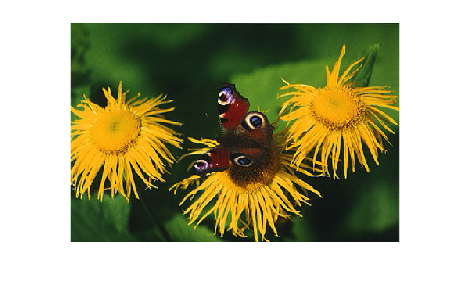

imshow(b68)

imwrite(b68, 'b68.png')